# Testing different numerical differentiation methods

MATLAB has built in functions for derivatives, but, they're slow; we have to define a function, differentiate it, and then evaluate it in a certain point, but what if we could approximate it to a certain point so that the error is meaningless to us? For this purpose, numerical differentiation methods were created, so that we could compute this operation in constant time $O(1)$, with a certain error that can be negligible according to which parameters we choose.

We'll be comparing between numerical differentiation methods for the first derivative and exploring a numerical method for the second derivative, these methods are

forwards differentiation,


$$f'(x) \approx \frac{f(x+h) - f(x)}{h}$$


backwards differentiation,


$$f'(x) \approx \frac{f(x) - f(x-h)}{h}$$


abbreviated central differentiation,


$$f'(x) \approx \frac{f(x+h) - f(x-h)}{2h}$$


and, central differentiation


$$f'(x) \approx \frac{-f(x+2h) + 8f(x+h) - 8f(x-h) + f(x-2h)}{12h}$$


for the first derivative. For the second derivative we have abbreviated central differentiation


$$f''(x) \approx \frac{f(x+h) - 2f(x) + f(x-h)}{h^2}$$


The point of this experiment is to find a numerical method that 

- minimizes the error that approximation methods create,

- minimizes truncation and rounding errors,

- and, satisfies our needs for accuracy of an evaluated function

## First derivative

The test parameters and different vectors to be utilized are declared and instantiated here

syms x
f1 = -0.1*x^4 - 0.15*x^3 - 0.5*x^2 - 0.25*x + 1.2; % test function
f2 = x^6 - 1; % test function

p = 0.5; % point to calculate the derivative
z = 0:32; % iteration vector to calculate h
n = length(z); % length of the previous vector
u = zeros(1, n); % vector for the values of the first derivative of f1
y = zeros(1, n); % vector for the values of the first derivative of f2

hF1 = zeros(1, n); % vector for the step size of every iteration of the f1 derivative
errorsF1 = zeros(1, n); % vector for the absolute error of the f1 derivative
hF2 = zeros(1, n); % vector for the step size of every iteration of the f2 derivati
errorsF2 = zeros(1, n); % vector for the absolute error of the f2 derivative
f1P = subs(diff(f1), x, p); % symbolic calculation of the f1 derivative for error determination
f2P = subs(diff(f2), x, p); % symbolic calculation of the f2 derivative for error determination

### Forwards differentiation

Using $f'(x) \approx \frac{f(x+h) - f(x)}{h}$, we'll approximate the derivative, using different $h$ parameters, starting from 1 to test if diminishing $h$ does make a difference in the error or not.

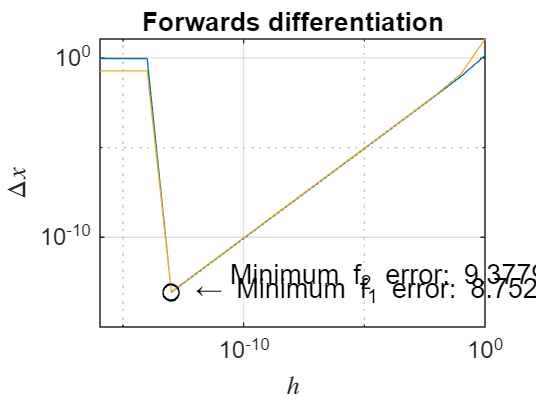

% calculate the values
parfor i = 1:n
    step = 1*0.1^z(i);
    
    [u(i), hF1(i), errorsF1(i)] = ... 
        forwardsFirstDerivative(f1, x, [p p+step], f1P);

    [y(i), hF2(i), errorsF2(i)] = ...
        forwardsFirstDerivative(f2, x, [p p+step], f2P);
end

[ymin, idx] = min(errorsF1); % check for the minimum error calculated in f1

loglog(hF1, errorsF1) % plot f1 errors in log scale

grid on
hold on

loglog(hF1(idx), ymin, 'ko') % plot minimum found error for f1
text(hF1(idx), ymin, [' \leftarrow Minimum f_1 error: ',num2str(ymin)]);
format longE


loglog(hF2, errorsF2)
[ymin, idx] = min(errorsF2); % check for the minimum error posible in f2
loglog(hF2(idx), ymin, 'ko') % plot said value
text(hF2(idx), ymin+5*ymin, ['    Minimum f_2 error: ',num2str(ymin)]);


hold off

title('Forwards differentiation')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

sprintf('Minimum error h for f1: %0.5e \n', hF1(idx))

ans =     'Minimum error h for f1: 1.00031e-13 
     '


sprintf('Minimum error h for f2: %0.5e \n', hF2(idx))

ans =     'Minimum error h for f2: 1.00031e-13 
     '


### Backwards differentiation

Repeating the past experiment, but this time using the backwards difference method$f'(x) \approx \frac{f(x) - f(x-h)}{h}$.

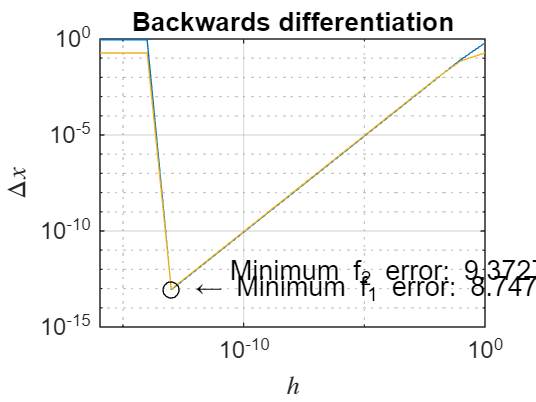

parfor i = 1:n
    step = 1*0.1^z(i);

    [u(i), hF1(i), errorsF1(i)] = ...
        backwardsFirstDerivative(f1, x, [p p-step], f1P);

    [y(i), hF2(i), errorsF2(i)] = ...
        backwardsFirstDerivative(f2, x, [p p-step], f2P);
end

[ymin, idx] = min(errorsF1);

loglog(hF1, errorsF1)

grid on
hold on

loglog(hF1(idx), ymin, 'ko')
text(hF1(idx), ymin, [' \leftarrow Minimum f_1 error: ',num2str(ymin)]);

loglog(hF2, errorsF2)
[ymin, idx] = min(errorsF2);
loglog(hF2(idx), ymin, 'ko')
text(hF2(idx), ymin+5*ymin, ['    Minimum f_2 error: ',num2str(ymin)]);

hold off

title('Backwards differentiation')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

sprintf('Minimum error h for f1: %0.5e \n', hF1(idx))

ans =     'Minimum error h for f1: 9.99756e-14 
     '


sprintf('Minimum error h for f2: %0.5e \n', hF2(idx))

ans =     'Minimum error h for f2: 9.99756e-14 
     '


### Abbreviated central differentiation

Same as past two experiments, but now using the abbreviated central differentiation método, defined as  $f'(x) \approx \frac{f(x+h) - f(x-h)}{2h}$.

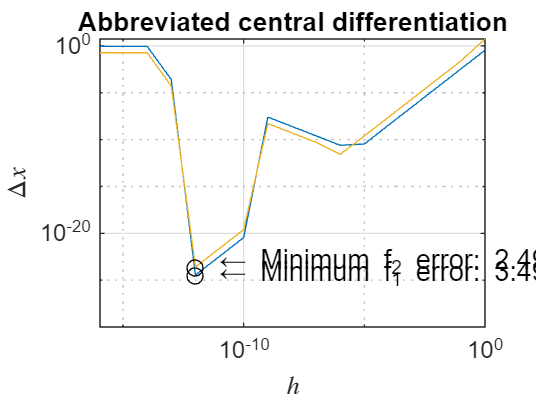

parfor i = 1:n
    step = 1*0.1^z(i);

    [u(i), hF1(i), errorsF1(i)] = ...
        abbreviatedCentralFirstDerivative(f1, x, [p+step p p-step], f1P);

    [y(i), hF2(i), errorsF2(i)] = ...
        abbreviatedCentralFirstDerivative(f2, x, [p+step p p-step], f2P);
end

[ymin, idx] = min(errorsF1);

loglog(hF1, errorsF1)

grid on
hold on

loglog(hF1(idx), ymin, 'ko')
text(hF1(idx), ymin, [' \leftarrow Minimum f_1 error: ',num2str(ymin)]);

loglog(hF2, errorsF2)
[ymin, idx] = min(errorsF2);
loglog(hF2(idx), ymin, 'ko')
text(hF2(idx), ymin+2*ymin, [' \leftarrow Minimum f_2 error: ',num2str(ymin)]);

hold off

title('Abbreviated central differentiation')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

sprintf('Minimum error h for f1: %0.5e \n', hF1(idx))

ans =     'Minimum error h for f1: 9.99978e-13 
     '


sprintf('Minimum error h for f2: %0.5e \n', hF2(idx))

ans =     'Minimum error h for f2: 9.99978e-13 
     '


### Central differentiation

Same as last three experiments, but now using the central differentiation formula, defined as $f'(x) \approx \frac{-f(x+2h) + 8f(x+h) - 8f(x-h) + f(x-2h)}{12h}$.

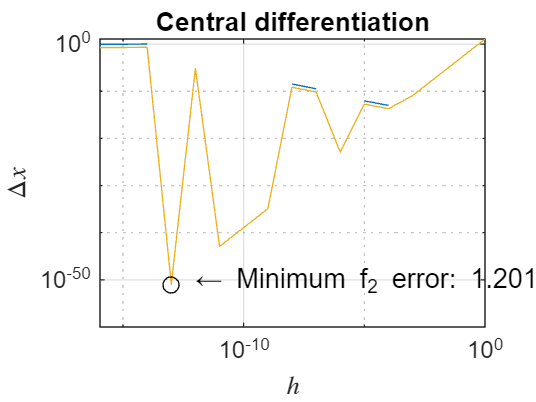

parfor i = 1:n
    step = 1*0.1^z(i);

    [u(i), hF1(i), errorsF1(i)] = ...
        centralFirstDerivative(f1, x, [p+2*step p+step p p-step p-2*step], f1P);

    [y(i), hF2(i), errorsF2(i)] = ...
        centralFirstDerivative(f2, x, [p+2*step p+step p p-step p-2*step], f2P);
end

loglog(hF1, errorsF1, 'Color','#0072BD')

% since central differentiation has an O(h^4) which is the same exponent as
% the function, this falls in no truncation errors, which creates
% increasing rounding errors which results in the graphic created by this
% code

grid on
hold on

loglog(hF2, errorsF2, 'color','#EDB120')
[ymin, idx] = min(errorsF2);
loglog(hF2(idx), ymin, 'ko')
text(hF2(idx), ymin+2*ymin, [' \leftarrow Minimum f_2 error: ',num2str(ymin)]);

hold off

title('Central differentiation')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

sprintf('Minimum error h for f1: %0.5e \n', hF1(idx))

ans =     'Minimum error h for f1: 1.00031e-13 
     '


sprintf('Minimum error h for f2: %0.5e \n', hF2(idx))

ans =     'Minimum error h for f2: 1.00031e-13 
     '


## Second derivative

Here are the parameters to be used to calculate the second derivative experiments.

f1PP = subs(diff(diff(f1)), x, p);
f2PP = subs(diff(diff(f2)), x, p);

### Abbreviated central differentiation

Repeating the same experiment than before, but this time calculating the second derivative using the abbreviated central differentiation method for this, its formula is $f''(x) \approx \frac{f(x+h) - 2f(x) + f(x-h)}{h^2}$.

parfor i = 1:n
    step = 1*0.1^z(i);

    [u(i), hF1(i), errorsF1(i)] = ...
        abbreviatedCentralSecondDerivative(f1, x, [p+step p p-step], f1PP);

    [y(i), hF2(i), errorsF2(i)] = ...
        abbreviatedCentralSecondDerivative(f2, x, [p+step p p-step], f2PP);
end

[ymin, idx] = min(errorsF1);

loglog(hF1, errorsF1)

grid on
hold on


idx =     14


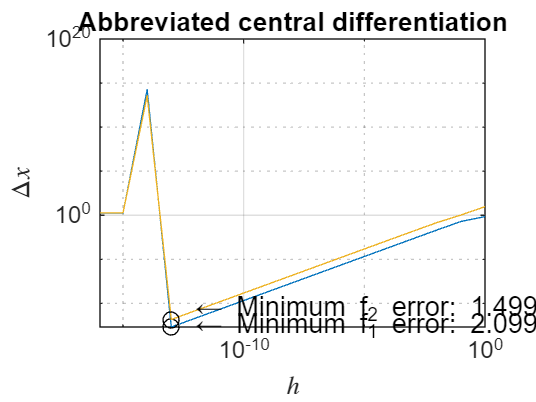

loglog(hF1(idx), ymin, 'ko')
text(hF1(idx), ymin, [' \leftarrow Minimum f_1 error: ',num2str(ymin)]);

loglog(hF2, errorsF2)
[ymin, idx] = min(errorsF2);
loglog(hF2(idx), ymin, 'ko')
text(hF2(idx), ymin+10*ymin, [' \leftarrow Minimum f_2 error: ',num2str(ymin)]);

hold off

title('Abbreviated central differentiation')
xlabel('$h$','interpreter','latex')
ylabel('$\Delta x$', 'Interpreter','latex')

sprintf('Minimum error h for f1: %0.5e \n', hF1(idx))

ans =     'Minimum error h for f1: 9.99756e-14 
     '


sprintf('Minimum error h for f2: %0.5e \n', hF2(idx))

ans =     'Minimum error h for f2: 9.99756e-14 
     '


## Conclusion

After studying different numerical differentiation methods (forwards differentiation, backwards differentiation, abbreviated central differentiation and central differentiation), we can reduce that there are two types of numerical errors general in each one: the truncation and rounding errors, this aside from the errors that approximation methods already create.

As we make $h$ smaller, we observe a reduction in truncation errors. However, at the same time, since a decrease in $h$ can lead to subtraction cancellation or an increase in the number of calculations, truncation errors decrease as rounding errors increase. The choice of differentiation method may depend on the specific function being approximated and the required accuracy. In some cases, a less accurate method may be sufficient, while in other cases a more accurate method may be needed. This experiment shows graphically the compensation between these two errors. In each case, the critical point (the ideal $h$ that gives us the minimum error) was identified, beyond which rounding errors begin to cancel the benefits of reducing the size of $h$.

Particularly, in the case of central differentiation, since it's error is equal to the highest power of $f_1$, it creates a weird situation where we have "0" error due to the using the Taylor's series' approximation in $n$ to the 4th order in this method, despite us knowing cero error is impossible. This creates a scenario where having less error might lead to bigger mistakes thanks to rounding errors increasing without us knowing, thus proving that using the lowest error method is not always the correct solution for certain problems. Still, we can observe that a tendency of the best $h$ being around $1\times10^{-13}$ is present through all the methods.

To conclude, the code provides a good analysis of the performance of different numerical differentiation methods, seeing their accuracy to step size variations. The visualizations and identified minimum errors leads to the understanding of the behavior of each method based on the specific characteristics of the functions and desired accuracy.

## References

- Steven Chapra & Raymond Canale, (2015). Cap.21, *Métodos Numéricos para Ingenieros (pp.548-560)*, McGraw- Hill, Séptima edición, 2015. 

- Matlab (2024). *Matlab*. Recuperado el 28 de enero de 2024 de: [MATLAB Documentation - MathWorks América Latina](https://la.mathworks.com/help/matlab/)